# **Escuela CNS: Analisis de series de tiempo - Día 3**

**A partir de los parámetros obtenidos en el primer día de este taller, se construirán un par de biomarcadores que nos ayudarán a detectar, desde este punto de vista, episodios de fibrilación auricular paroxística.**

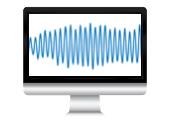


load("px_actividad.mat");

% Separar columnas de tiempo y valor de la señal
% tiempo = data(:, 1);
% valor = data(:, 2);
% 
% tiempo = tiempo(1:8500000);
% valor = valor(1:8500000);

fs=250;

tiempo = seconds(tiempo); 
tiempo.Format = 'hh:mm:ss.SSS';

inicio_episodios = [
    duration("00:37:06.711"), 
    duration("00:47:44.443"), 
    duration("02:23:13.895"), 
    duration("03:19:55.153"), 
    duration("04:02:35.684"), 
    duration("04:37:11.904"), 
    duration("08:32:06.960")
];

fin_episodios = [
    duration("00:38:43.887"), 
    duration("00:48:16.300"), 
    duration("02:23:35.885"), 
    duration("03:20:12.715"), 
    duration("04:05:09.748"), 
    duration("04:37:31.979"), 
    duration("08:32:24.941")
];

periodo_sano = [duration("00:21:44.711"), duration("00:25:44.443")];

inicio_episodios_sec = seconds(inicio_episodios);
fin_episodios_sec = seconds(fin_episodios);

% === Filtro de media móvil + paso alto ===
window_size = 150;
valor_filtrado_ma = movmean(valor, window_size);
paso_altas_ma = valor - valor_filtrado_ma;

% === Filtro Butterworth de orden 5 ===
order = 5;
[b5, a5] = butter(order, 20 / (fs / 2), 'low');
valor_filtrado_avanzado = filtfilt(b5, a5, paso_altas_ma);

% Detectar espigas R en TODA la señal (no solo en el episodio)
[~, locs] = findpeaks(valor_filtrado_avanzado, 'MinPeakHeight', 0.4, ...
                     'MinPeakDistance', round(0.20 * fs));
%aclarar poner gráfico
fprintf('Picos detectados: %d\n', length(locs));

Picos detectados: 1208



tiempo_sec = seconds(tiempo);
R_times = tiempo_sec(locs); 
RR_intervals_sec = diff(R_times); 

windowSize = 20; % Tamaño de la ventana de promediacion
RR_intervals_filtered = movmean(RR_intervals_sec, windowSize);

% Calcular tasa de cambio (dHRV/dt)
dHRV_dt = abs(diff(RR_intervals_filtered) ./ diff(R_times(2:end)));

% vector de tiempo para la derivada 
time_derivative = R_times(3:end); 
dHRV_dt = movmean(dHRV_dt, 30);

ventana_seg = 6;
ventana_muestras = round(ventana_seg * fs);

% Inicialización
n_muestras = length(valor_filtrado_avanzado);
num_ventanas = floor(n_muestras / ventana_muestras);

cresta = zeros(1, num_ventanas);
tiempo_fc = zeros(1, num_ventanas);


for k = 1:num_ventanas
    % Índices de la ventana actual
    idx_inicio = (k - 1) * ventana_muestras + 1;
    idx_fin = k * ventana_muestras;
   
    segmento = valor_filtrado_avanzado(idx_inicio : idx_fin);
    
    % Cálculo del factor de cresta
    rms_val = rms(segmento);
    pico_val = max(abs(segmento));
    factor_cresta = pico_val / rms_val;
    
    % Guardar resultados
    cresta(k) = factor_cresta;
    tiempo_fc(k) = (idx_inicio + idx_fin) / 2 / fs;  % tiempo medio de la ventana
end

%suavizado de la serie de tiempo
cresta = movmean(cresta, 20);

% Tasa de cambio (derivada temporal del factor de cresta)
tasa_cambio = abs(diff(cresta) ./ diff(tiempo_fc))                                 ;
tiempo_fc_derivada = tiempo_fc(1:end-1) + diff(tiempo_fc)/2;

tasa_cambio = movmean(tasa_cambio, 60);

% --- Parámetros ---
ventana_seg = 6;                      % Duración de cada ventana en segundos
ventana_muestras = round(ventana_seg * fs);  % Duración en muestras

% --- Inicialización ---
n_muestras = length(valor_filtrado_avanzado);
num_ventanas = floor(n_muestras / ventana_muestras);

amplitud_R = zeros(1, num_ventanas);      % amplitudes promedio por ventana
tiempo_R = zeros(1, num_ventanas);        % tiempos centrales de cada ventana

% --- Calcular amplitud promedio de espigas R por ventana ---
for k = 1:num_ventanas
    % Índices de la ventana actual
    idx_inicio = (k - 1) * ventana_muestras + 1;
    idx_fin = k * ventana_muestras;
    
    % Tiempo central de la ventana en segundos
    tiempo_R(k) = (idx_inicio + idx_fin) / 2 / fs;
    
    % Picos R dentro de esta ventana (usando posiciones 'locs')
    locs_en_ventana = locs(locs >= idx_inicio & locs <= idx_fin);
    
    if ~isempty(locs_en_ventana)
        % Tomar amplitudes de las espigas R (usando señal original filtrada)
        amplitudes = valor_filtrado_avanzado(locs_en_ventana);
        amplitud_R(k) = mean(amplitudes);  % promedio de amplitudes en la ventana
    else
        amplitud_R(k) = NaN;  % si no hay picos R en esa ventana
    end
end


% --- Suavizado opcional (antes de derivar) ---
amplitud_R_suavizada = movmean(amplitud_R, 5, 'omitnan');

% --- Tasa de cambio de la amplitud de espigas R ---
tasa_cambio_amp = abs(diff(amplitud_R_suavizada) ./ diff(tiempo_R));
tiempo_cambio_amp = tiempo_R(1:end-1) + diff(tiempo_R) / 2/fs;  % tiempo medio entre ventanas

% --- Suavizado adicional opcional ---
tasa_cambio_amp = movmean(tasa_cambio_amp, 10);

# #Sección 2

## Definición de Umbrales 

El análisis del comportamiento de los parámetros antes, durante y después de los episodios de fibrilación auricular permite identificar patrones característicos asociados a cada fase. Estos patrones pueden facilitar la definición de umbrales que delimiten el rango de valores considerados normales o nominales. De esta manera, es posible establecer criterios que distingan entre un comportamiento fisiológico típico y uno que indique la presencia de un episodio de fibrilación auricular.

Para el paciente de este estudio, los valores definidos para cada uno de los parámetros se describen en el siguiente bloque.

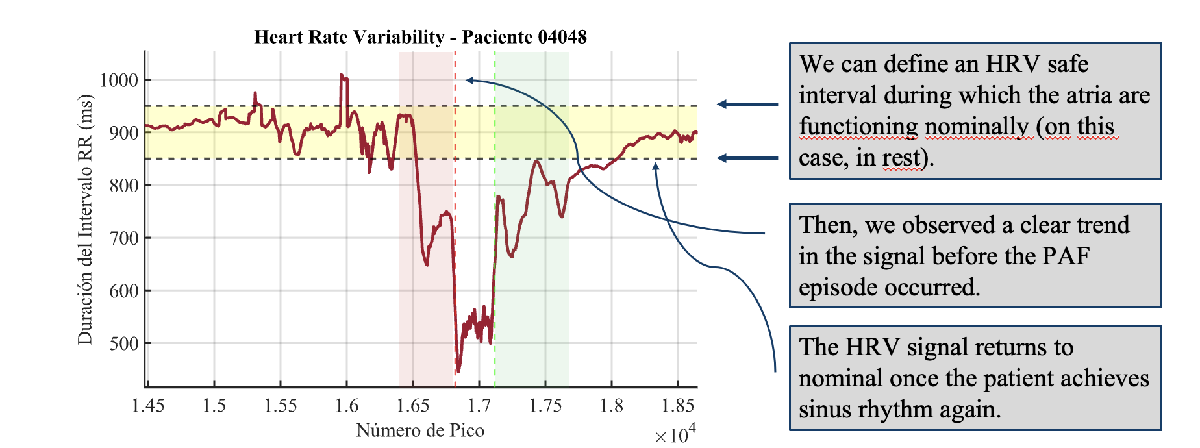

promedio_fc = mean(cresta);
promedio_fc_dt = mean(tasa_cambio);

promedio_hrv = mean(RR_intervals_filtered);
promedio_hrv_dt = mean(dHRV_dt);

promedio_amplitud = mean(amplitud_R_suavizada);
promedio_amplitud_dt = mean(tasa_cambio_amp);


% Crear la tabla
variable = {'Factor de Cresta'; 'HRV'; 'Amplitud promedio'};
valor_promedio = [promedio_fc; promedio_hrv; promedio_amplitud];
derivada_temporal = [promedio_fc_dt; promedio_hrv_dt; promedio_amplitud_dt];

tabla_comparativa = table(variable, valor_promedio, derivada_temporal);
disp(tabla_comparativa);

          variable           valor_promedio    derivada_temporal
    _____________________    ______________    _________________

    {'Factor de Cresta' }        5.0942            0.0088664    
    {'HRV'              }        8.2053              0.55137    
    {'Amplitud promedio'}           NaN                  NaN    



# #Sección 3

## Deltas

En esta sección se definen los deltas para los cuales vamos a manejar los umbrales, y más en particular, las condiciones de detección.

a1 = 2; a2 = 1.3;
b1 = 2; b2 = 0.8;
c1 = 2; c2 = 1.25;

delta_hrv = a1*std(RR_intervals_filtered);
delta_hrv_dt = a2*std(dHRV_dt);

delta_fc = b1*std(cresta);
delta_fc_dt = b2*std(tasa_cambio);

delta_amplitud = c1*std(amplitud_R_suavizada);
delta_amplitud_dt = c2*std(tasa_cambio_amp);


%umbrales para el factor de cresta
umbral_factor_cresta_max = promedio_fc + delta_fc;
umbral_factor_cresta_min = promedio_fc - delta_fc;

umbral_tasa_cambio_fc_max = promedio_fc_dt + delta_fc_dt;
umbral_tasa_cambio_fc_min = 0;

%umbrales para la amplitud
umbral_amplitud_picos_max = promedio_amplitud + delta_amplitud;
umbral_amplitud_picos_min = promedio_amplitud - delta_amplitud;

umbral_tasa_cambio_max = promedio_amplitud_dt + delta_amplitud_dt;
umbral_tasa_cambio_min = 0;

%umbrales para el hrv
umbral_hrv_min = promedio_hrv + delta_hrv;
umbral_hrv_max = promedio_hrv - delta_hrv;

umbral_tasa_cambio_hrv_max = promedio_hrv_dt + delta_hrv_dt;
umbral_tasa_cambio_hrv_min = 0;

# Sección #4

## Sincronización de la base temporal

A nivel de simulación, es fundamental que todas las señales analizadas compartan una misma base temporal para permitir una comparación coherente entre ellas. Por esta razón, en el siguiente bloque de código se realiza un proceso de sincronización temporal mediante interpolación. Este procedimiento reescala todas las señales calculadas —como el factor de cresta, la amplitud media, el HRV y sus respectivas derivadas— hacia un eje de tiempo común.

tiempo_base = tiempo_fc_derivada(:);  % eje común

% Interpolamos todas las señales a esa escala de tiempo
fc_interp        = interp1(tiempo_fc, cresta, tiempo_base, 'linear', NaN);
dfc_dt_interp    = interp1(tiempo_fc_derivada, tasa_cambio, tiempo_base, 'linear', NaN);

amp_interp       = interp1(tiempo_R, amplitud_R_suavizada, tiempo_base, 'linear', NaN);
damp_dt_interp   = interp1(tiempo_cambio_amp, tasa_cambio_amp, tiempo_base, 'linear', NaN);

hrv_interp       = interp1(R_times(2:end), RR_intervals_filtered, tiempo_base, 'linear', NaN);
dhrv_dt_interp   = interp1(time_derivative, dHRV_dt, tiempo_base, 'linear', NaN);

# Sección #5

## Condiciones de detección

En este bloque se evalúa si cada parámetro supera los umbrales definidos. Para ello, se utilizan comparaciones lógicas que generan vectores booleanos del mismo tamaño que la base temporal, indicando en cada instante si se ha producido una violación del umbral. Finalmente, estos vectores se suman de forma elemento a elemento, obteniendo así un contador por instante de tiempo que indica cuántos parámetros simultáneamente se encuentran fuera de sus rangos "nominales".

% Factor de cresta
cond_fc     = (fc_interp < umbral_factor_cresta_min) | (fc_interp > umbral_factor_cresta_max);
cond_dfc    = (dfc_dt_interp < umbral_tasa_cambio_fc_min) | (dfc_dt_interp > umbral_tasa_cambio_fc_max);

% Amplitud de picos R
cond_amp    = (amp_interp < umbral_amplitud_picos_min) | (amp_interp > umbral_amplitud_picos_max);
cond_damp   = (damp_dt_interp < umbral_tasa_cambio_min) | (damp_dt_interp > umbral_tasa_cambio_max);

% HRV
cond_hrv    = (hrv_interp < umbral_hrv_max) | (hrv_interp > umbral_hrv_min);  % valores fuera del rango
cond_dhrv   = (dhrv_dt_interp < umbral_tasa_cambio_hrv_min) | (dhrv_dt_interp > umbral_tasa_cambio_hrv_max);


detector_estatico = cond_fc + cond_dfc + cond_amp + cond_damp + cond_hrv + cond_dhrv;  % suma lógica

# Sección #6

## Visualización de parámetros y umbrales de detección.

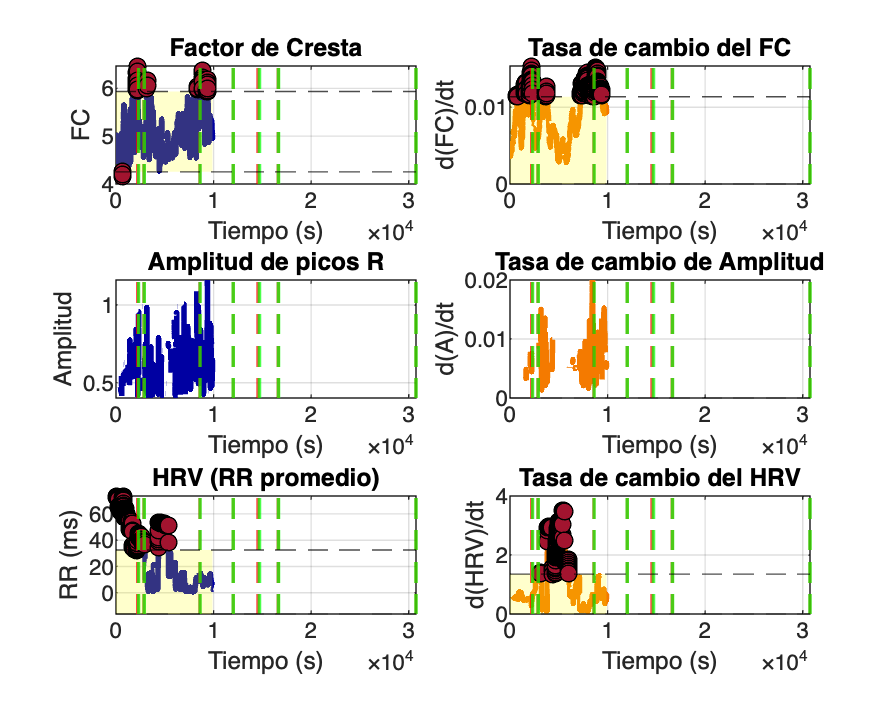

figure('Name', 'Indicadores y umbrales por ventana de 6 segundos', 'Position', [100, 100, 1000, 800]);

% --- Parámetro 1: Factor de cresta ---
subplot(3,2,1);
plot(tiempo_base, fc_interp, 'Color', '#0000A2', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_factor_cresta_min, size(tiempo_base)); flipud(repmat(umbral_factor_cresta_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_factor_cresta_min, '--k');
yline(umbral_factor_cresta_max, '--k');
plot(tiempo_base(cond_fc), fc_interp(cond_fc), 'ko','MarkerFaceColor', "#A2142F");
title('Factor de Cresta');
xlabel('Tiempo (s)');
ylabel('FC');
grid on;

% --- Parámetro 2: d(FC)/dt ---
subplot(3,2,2);
plot(tiempo_base, abs(dfc_dt_interp), 'Color', '#F47A00', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_tasa_cambio_fc_min, size(tiempo_base)); flipud(repmat(umbral_tasa_cambio_fc_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_tasa_cambio_fc_min, '--k');
yline(umbral_tasa_cambio_fc_max, '--k');
plot(tiempo_base(cond_dfc), dfc_dt_interp(cond_dfc), 'ko','MarkerFaceColor', "#A2142F");
title('Tasa de cambio del FC');
xlabel('Tiempo (s)');
ylabel('d(FC)/dt');
grid on;

% --- Parámetro 3: Amplitud de picos R ---
subplot(3,2,3);
plot(tiempo_base, amp_interp, 'Color', '#0000A2', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_amplitud_picos_min, size(tiempo_base)); flipud(repmat(umbral_amplitud_picos_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_amplitud_picos_min, '--k');
yline(umbral_amplitud_picos_max, '--k');
plot(tiempo_base(cond_amp), amp_interp(cond_amp), 'ko','MarkerFaceColor', "#A2142F");
title('Amplitud de picos R');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

% --- Parámetro 4: d(Amplitud)/dt ---
subplot(3,2,4);
plot(tiempo_base, abs(damp_dt_interp), 'Color', '#F47A00', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_tasa_cambio_min, size(tiempo_base)); flipud(repmat(umbral_tasa_cambio_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_tasa_cambio_min, '--k');
yline(umbral_tasa_cambio_max, '--k');
plot(tiempo_base(cond_damp), damp_dt_interp(cond_damp), 'ko','MarkerFaceColor', "#A2142F");
title('Tasa de cambio de Amplitud');
xlabel('Tiempo (s)');
ylabel('d(A)/dt');
grid on;

% --- Parámetro 5: HRV ---
subplot(3,2,5);
plot(tiempo_base, hrv_interp, 'Color', '#0000A2', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_hrv_min, size(tiempo_base)); flipud(repmat(umbral_hrv_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_hrv_min, '--k');
yline(umbral_hrv_max, '--k');
plot(tiempo_base(cond_hrv), hrv_interp(cond_hrv), 'ko','MarkerFaceColor', "#A2142F");
title('HRV (RR promedio)');
xlabel('Tiempo (s)');
ylabel('RR (ms)');
grid on;

% --- Parámetro 6: d(HRV)/dt ---

subplot(3,2,6);
plot(tiempo_base, abs(dhrv_dt_interp), 'Color', '#F47A00', 'LineWidth', 2);
hold on;
fill([tiempo_base; flipud(tiempo_base)], ...
     [repmat(umbral_tasa_cambio_hrv_min, size(tiempo_base)); flipud(repmat(umbral_tasa_cambio_hrv_max, size(tiempo_base)))], ...
     [1 1 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end
yline(umbral_tasa_cambio_hrv_min, '--k');
yline(umbral_tasa_cambio_hrv_max, '--k');
plot(tiempo_base(cond_dhrv), dhrv_dt_interp(cond_dhrv), 'ko','MarkerFaceColor', "#A2142F");
title('Tasa de cambio del HRV');
xlabel('Tiempo (s)');
ylabel('d(HRV)/dt');
grid on;

linkaxes([subplot(3,2,1), subplot(3,2,2), subplot(3,2,3), subplot(3,2,4), subplot(3,2,5) subplot(3,2,6)], 'x'); 

# Sección #7

## Visualización de detector estático

En el siguiente segmento se realizará una primera visualización de como actua el detector basado en la asignación de umbrales estáticos. 

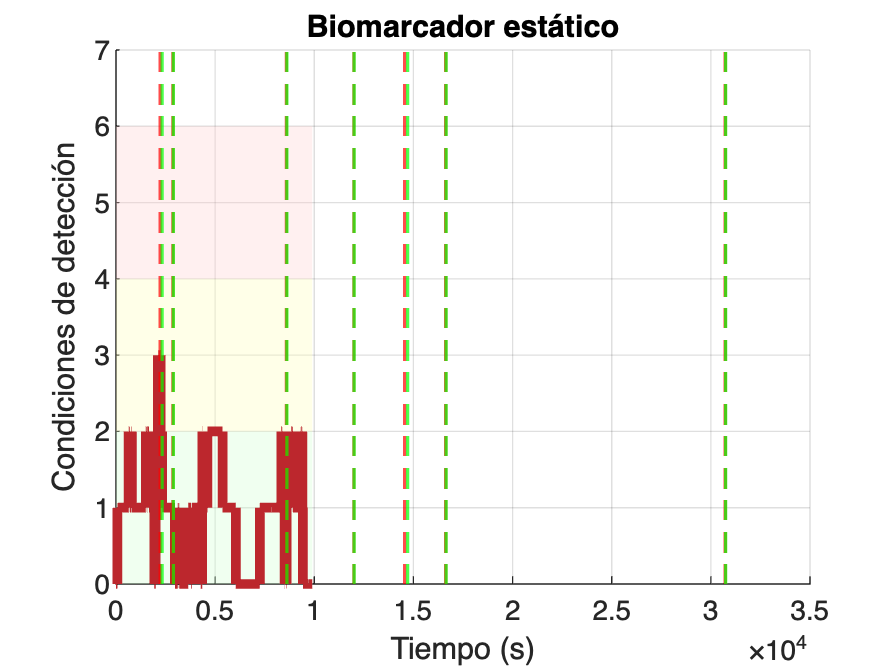

figure;
hold on;

% Límites del eje x para las franjas de color
x_limits = [min(tiempo_base), max(tiempo_base)];

% Rango verde (0 a 2)
fill([x_limits fliplr(x_limits)], [0 0 2 2], [0.8 1 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Rango amarillo (2 a 4)
fill([x_limits fliplr(x_limits)], [2 2 4 4], [1 1 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Rango rojo (4 a 6)
fill([x_limits fliplr(x_limits)], [4 4 6 6], [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Traza principal
stairs(tiempo_base, detector_estatico, '-', 'LineWidth', 3.5, 'Color', '#BC272D');

xlabel('Tiempo (s)');
ylabel('Condiciones de detección');
title('Biomarcador estático');
ylim([0 7]);

% Líneas de inicio y fin de episodios
for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

grid on;

uistack(findall(gca, 'Type', 'line'), 'top');


# Sección #8

## Biomarcador dinámico

Con la finalidad de filtrar falsos positivos y concentrarnos en los episodios más significativos, se propone implementar un biomarcaor dinámico a partir del resultado obtenido con el detector estático. Este último servirá como entrada para brindar una nueva salida más precisa.

El biomarcador dinámico es un sistema de sincronización maestro-esclavo, donde nosotros visualizaremos el error de sincronización entre ambos sistemas. La fuerza de acoplamiento será una versión re-escalada del biomarcador estático.

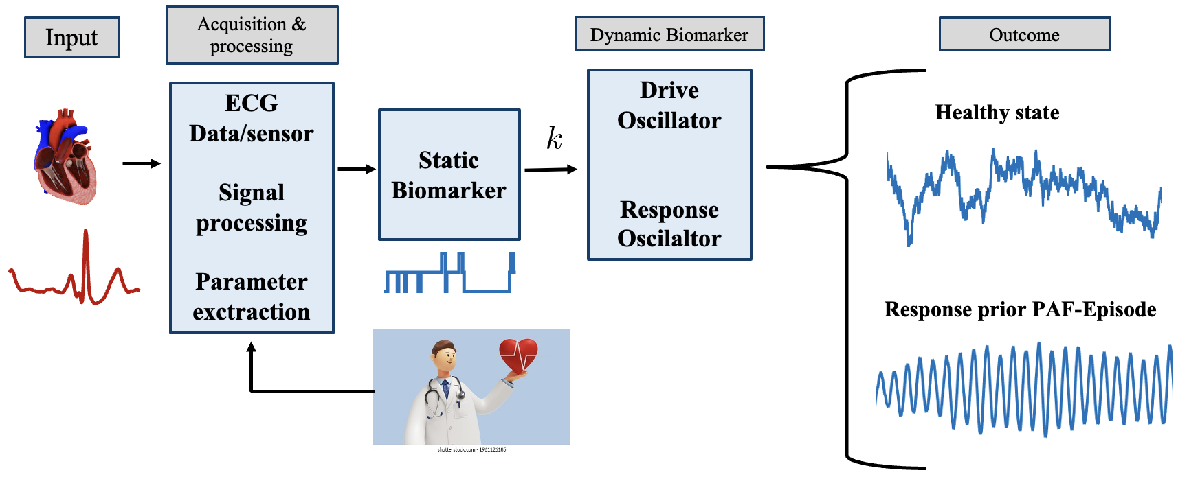

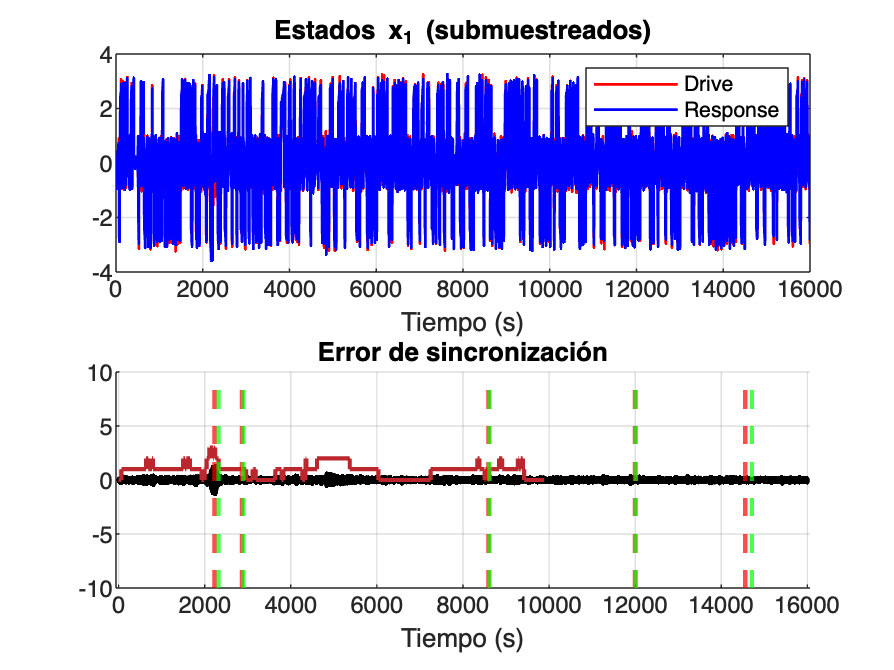

ventana_duracion = 6;
tiempo_base = (0:length(detector_estatico)-1) * ventana_duracion;  % desde 0: [0,6,12,...]

in_sim = 0;
fin_sim = 16000;

alpha = 0.8;
A = [0 1 0; 0 0 1; -alpha -alpha -alpha];
B = [1; 0; 0];
C = [0 1 0];

sigma = 1;  % Nivel de ruido blanco gaussiano

% condiciones iniciales
x_d0 = [-1; 1; -1];
x_r0 = [-1; 1; -1];

dt = 0.001; % Paso de integración deseado
tspan = in_sim:dt:fin_sim; 
num_samples = length(tspan); 

% === Generación del ruido ===
noise = sigma * randn(6, num_samples); % Ruido normal (6 filas, 1 por variable)
noise = noise - mean(noise, 2); % Asegura media 0

% separar el ruido para drive y response
v_d_noise = noise(1:3, :)';  % sistema maestro
v_r_noise = noise(4:6, :)';  % sistema esclavo

sensibilidad =0.165;

% configuración de la ganancia k1
k1_vector = zeros(size(detector_estatico));
k1_vector(detector_estatico == 0) = 0.6;
k1_vector(detector_estatico >= 3) = sensibilidad;
intermedios = (detector_estatico > 0) & (detector_estatico < 3);
k1_vector(intermedios) = 0.6 - (0.6 - 0.15) * (detector_estatico(intermedios) / 3);

% precalcular k_t para todos los tiempos
k_t = interp1(tiempo_base, k1_vector, tspan, 'previous', 'extrap');

% matrices de resultados
X = zeros(num_samples, 6);
X(1,:) = [x_d0; x_r0]';

% Implementación de RK4
for i = 1:num_samples-1
    t = tspan(i);
    x = X(i,:)';
    
    % RK4 steps
    k1 = dt * sistema_completo(t, x, A, B, C, alpha, v_d_noise(i,:)', v_r_noise(i,:)', k_t(i));
    k2 = dt * sistema_completo(t + dt/2, x + k1/2, A, B, C, alpha, (v_d_noise(i,:)'+v_d_noise(i+1,:)')/2, (v_r_noise(i,:)'+v_r_noise(i+1,:)')/2, (k_t(i)+k_t(i+1))/2);
    k3 = dt * sistema_completo(t + dt/2, x + k2/2, A, B, C, alpha, (v_d_noise(i,:)'+v_d_noise(i+1,:)')/2, (v_r_noise(i,:)'+v_r_noise(i+1,:)')/2, (k_t(i)+k_t(i+1))/2);
    k4 = dt * sistema_completo(t + dt, x + k3, A, B, C, alpha, v_d_noise(i+1,:)', v_r_noise(i+1,:)', k_t(i+1));
    
    X(i+1,:) = X(i,:) + (k1 + 2*k2 + 2*k3 + k4)'/6;
end

% resultados
x_d = X(:, 1:3);
x_r = X(:, 4:6);
error = x_d - x_r;


skip = 1000;
t_plot = tspan(1:skip:end);
x_d_plot = x_d(1:skip:end, 1);
x_r_plot = x_r(1:skip:end, 1);
error_plot = error(1:skip:end, 1);

figure;
subplot(2,1,1);
plot(t_plot, x_d_plot, 'r', t_plot, x_r_plot, 'b', 'LineWidth', 1);
legend('Drive', 'Response');
title('Estados x_1 (submuestreados)');
xlabel('Tiempo (s)');
grid on;

subplot(2,1,2);
hold on;


for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

plot(t_plot, error_plot, 'k', 'LineWidth', 1.7);
hold on;


stairs(tiempo_base, detector_estatico, '-', 'LineWidth', 1.5, 'Color', '#BC272D');

ylim([-10 10]);
xlim([in_sim-60 fin_sim+60]) 

title('Error de sincronización');
xlabel('Tiempo (s)');
grid on;


%linkaxes([subplot(2,1,1), subplot(2,1,2), 'x']);

% figure;
% plot(x_d(:,1), x_d(:,2), 'r', 'LineWidth', 2); % Trayectoria del sistema drive
% hold on;
% plot(x_r(:,1), x_r(:,2), 'b', 'LineWidth', 2); % Trayectoria del sistema response
% xlabel('x_1');
% ylabel('x_2');
% title('Diagrama de fase: x_1 vs x_2');
% legend('Drive', 'Response');
% grid on;

%% Función del sistema completo para RK4
function dx = sistema_completo(t, x, A, B, C, alpha, v_d, v_r, k_1)
    x_d = x(1:3);
    x_r = x(4:6);
    
    % Error
    e = x_d - x_r;
    
    % Ganancia dinámica
    K = [k_1 k_1 k_1];

    % Ley de control
    u = K * e;
    
    % Función de conmutación
    b_x = b_func((x_d + x_r)/2, alpha);
    
    % Dinámicas
    dx_d = A * x_d + b_x + v_d;
    dx_r = A * x_r + b_x + B * u + v_r;
    
    dx = [dx_d; dx_r];
end

%% Función de conmutación 
function b_val = b_func(x, alpha)
    b_val = [0; 0; alpha * switch_function(x(1))];
end

%% Función auxiliar de conmutación 
function val = switch_function(x_i)
    if x_i < -1
        val = -2;
    elseif x_i > 1
        val = 2;
    else
        val = 0;
    end
end